# Plantilla problema práctica 1 Model. Exp.

Es necesario cargar los datos suministrados por la empresa en este punto

## Petición de la empresa

Cordial saludo ingenieros matemáticos. Nos comunicamos con ustedes porque necesitamos determinar un modelo para el comportamiento de cierta planta ultra secreta. Como podrán comprender, nos vemos en la obligación de reservarnos la mayor cantidad de información posible. Nosotros mismos ya hemos adelantado parte de los procesos necesarios para determinar el modelo. Sabemos que nuestra planta consta de una única entrada y una única salida, la entrada tiene un valor de 1000 unidades regularmente y la planta se mantiene en estado estacionario. Partiendo de este punto de estabilidad, nuestro anterior ingeniero varió el valor de la entrada en un rango de 500 a 1500 tal y como pueden ver a continuación

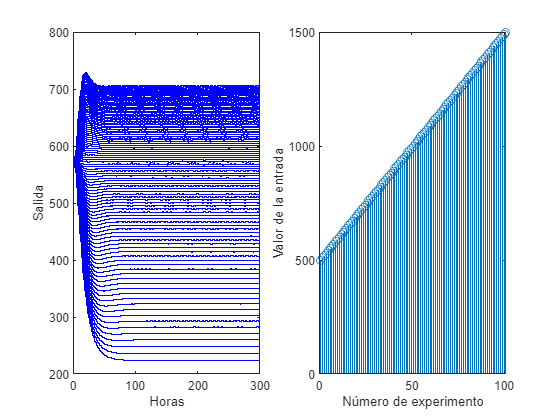

figure(1)
clf
subplot(1,2,1)
stairs(0:300,y_sample','b')
xlabel('Horas')
ylabel('Salida')
subplot(1,2,2)
stem(u_lineal)
xlabel('Número de experimento')
ylabel('Valor de la entrada')

Esta información se las compartimos a través de la matriz **y_sample** y el vector **u_lineal**. La primera fila de la matriz corresponde con el primer valor del vector como entrada. Para cada caso, se tomaron muestras del estado del sistema cada hora y esperamos hasta que el sistema se estabilizara. Luego, para un solo experimento, se aumentó lo máximo posible el esfuerzo de muestreo y se cambió la entrada del sistema de 1000 a 1120 de forma abrupta. Los datos de la respuesta del modelo se presentan a continuación

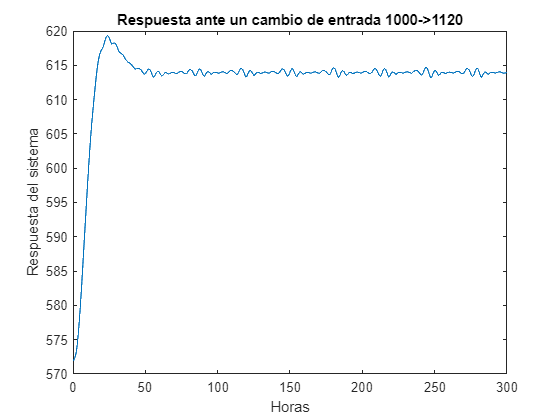

figure(2)
clf
plot(t,y_response)
xlabel('Horas')
ylabel('Respuesta del sistema')
title('Respuesta ante un cambio de entrada 1000->1120')

Con base en dicha información, nuestro anterior ingeniero decidió excitar el sistema con un periodo de muestreo de 1 hora y una señal PRBS (con un periodo igual al de muestreo) que variaba entre valores de 900 y 1120 para luego proceder a identificar un modelo apropiado para la planta, sin embargo, tuvimos que prescindir del ingeniero en este punto y el sistema no ha podido identificarse. Los datos recopilados se muestran a continuación

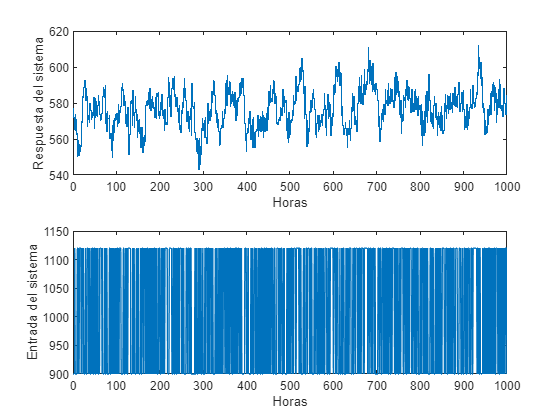

figure(3)
clf
subplot(2,1,1)
stairs(0:1000,y')
xlabel('Horas')
ylabel('Respuesta del sistema')
subplot(2,1,2)
plot(0:1000,u)
xlabel('Horas')
ylabel('Entrada del sistema')

Nos hemos contactado con ustedes con la esperanza de que puedan evaluar la metodología que siguió nuestro anterior ingeniero (si es adecuada o si modificarían algo) y, en caso de que lo consideren posible, concluir el proceso de identificación del sistema. Les solicitamos el mayor detalle posible en sus respuestas así como en la justificación de porqué deberíamos confiar o no en el modelo que ustedes puedan identificar. Estaremos muy atentos. 

## Respuesta a la empresa

A continuación desarrolle lo que la empresa le ha pedido.